# Demod and Sine Tests

## Clear Workspace

close all; clearvars; clc;

## Initialize Variables

outputRate = 1e6; % Sets the rate that the NI-Board output at
bufferForPreLoad = 500e3; % sets the length of buffer for preloading
pkpV = 1; % pk-pk voltage per frequency
frq = [20e3];
phase = 0;

t = (0:bufferForPreLoad-1)/outputRate; % Time Vector

## Compute Sample

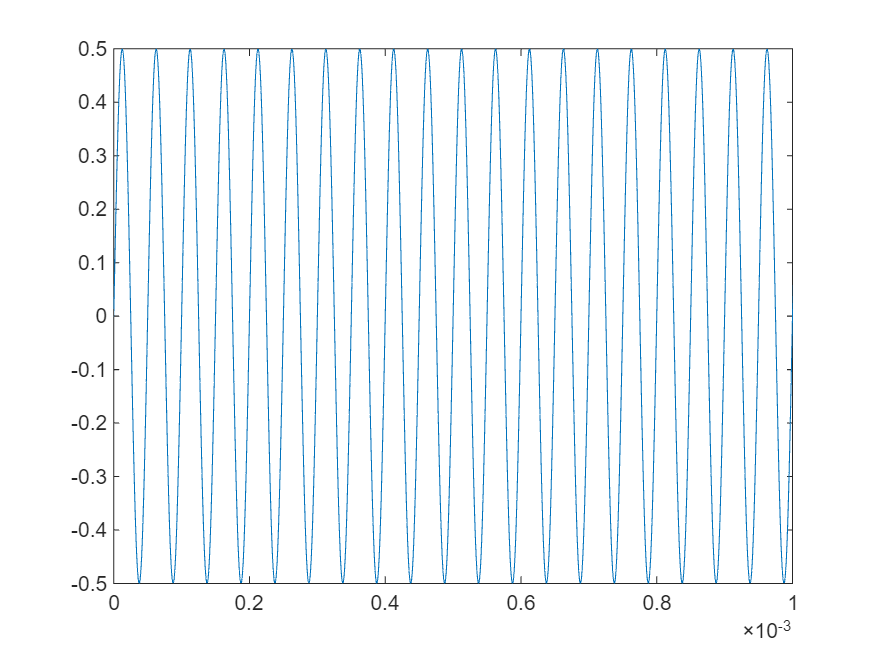

sig = createSine(pkpV/2, frq, 0, outputRate, "bipolar", bufferForPreLoad);
sig = sig(1:bufferForPreLoad);
figure
plot(t, sig)
xlim([0 1e-3])

## Compute FFT

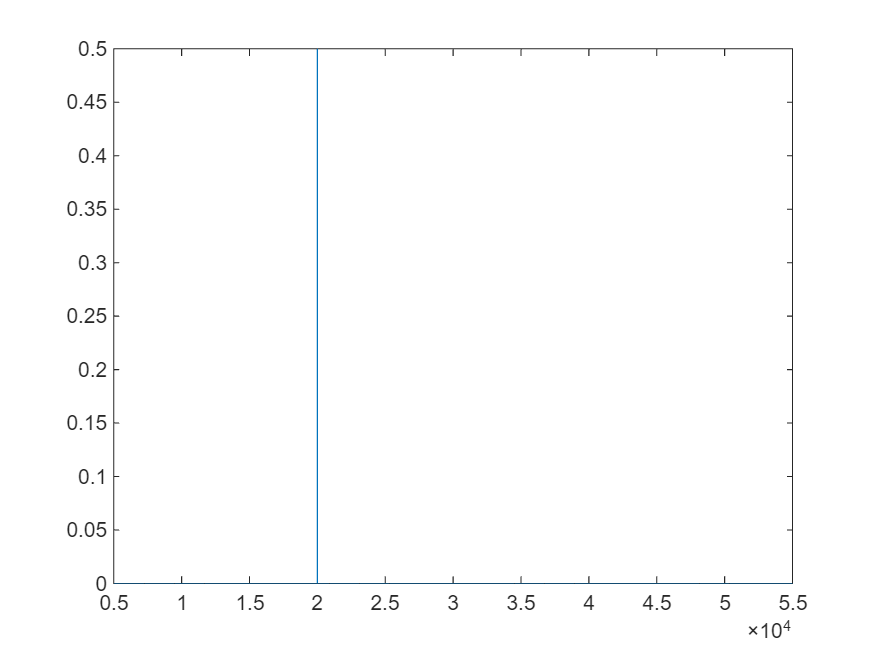

f_Hz = outputRate/bufferForPreLoad*(0:bufferForPreLoad-1);
sigFFT = fft(sig);
sigNormFFT = abs(sigFFT/bufferForPreLoad)*2;
figure
plot(f_Hz, sigNormFFT)
xlim([5e3 55e3])

## Demodulation

[demod, Epiv] = multiFreqDemod(sig, frq, bufferForPreLoad, outputRate);
demod

demod =     0.5000    0.0000    0.0000


## Sine Function

function sine = createSine(A, frq, phase, sampleRate, type, bufferForPreLoad)
    timeStep = 1/sampleRate; % period of the sampling frequency
    period = 1/eval(gcd(sym(frq))); % calculates the length of the period for a periodic signal
    samples = period/timeStep*2-1;
    t = ((0:samples)*timeStep)'; % calculates the time vector from the period
    y = sum(A*sin(2.*pi.*frq.*t+phase),2); % calculates the signal along the time vector
    
    if type == "unipolar"
        y = y + max(y); % if the signal is unipolar add the max amplitude to make it all positive
    end
    
    numCycles = ceil(bufferForPreLoad/(samples+1)); % calculate the number of cycles to make a full buffer for preloading
    sine = repmat(y, numCycles, 1); % extends the data vector to match or execed the buffer length
end

## Frequency Demodulation

function [ampPhase, Epiv] = multiFreqDemod(varargin) % signal, frq, sampleLen, sampleFreq or signal, Etot
    if nargin == 2
        phi_tot = varargin{2}*varargin{1};
    else
        k = 0:varargin{3}-1; % vector of n points
        tk = (k/varargin{4})'; % xAxis
        
        w = 2*pi*varargin{2};     % frequency converted to anglar frequency (rad/s)
        
        % matrix containing the desired frequency component of the system
        Etot = [sin(w.*tk), cos(w.*tk)];
        if(size(varargin{2})==1)
            Etot = [Etot, ones(1, length(tk))'];
        else
            for ii = 2:3:size(Etot,2)*1.5
                Etot = [Etot(:,1:ii), ones(1, length(tk))', Etot(:,ii+1:end)];
            end
        end
        % inverse of E * s^t (pinv)
        % phi1 = E(1)\signal; % gives alpha, beta and offset
        % phi2 = E(2)\signal;
        % phi3 = E(3)\signal;
        Epiv = pinv(Etot);
        phi_tot = Epiv*varargin{1}; % compute Alpha, Beta, and DC offset
        %phi_tot = lsqminnorm(Etot, signal); %(:,1); % compute Alpha, Beta, and DC offset
        
        phi_tot = reshape(phi_tot, [], 3); % rearragnge to useful order
        
    end
    for jj = 1:size(phi_tot,1)
        ampPhase(jj,:) = [sqrt(phi_tot(jj, 1)^2+phi_tot(jj, 2)^2)', atan2(phi_tot(jj, 2),phi_tot(jj, 1))' phi_tot(jj,3)]'; 
    end
    
    %ampPhase = ampPhase(1:2,length(frq)); % cut out dc as it is not needed
end